# Comments on analyse_stretch.m

## Purpose

Find transition point and distance dx in a unfolding or refolding stretch.

### Inputs

s: input struct with fields

    x: column array of extent 

    f: column array of force 

    t: column array of time values

### Outputs 

k:       Index of transition point in f. 

    k < 1: No transition found.  Negative k values indicate exit point, for debugging 

force:   Force at final unfolding or refolding event 

dx:       Change in extent from transition until force obtain ¨s value from before transition

Fdot: Force rate of change before transition

shift: Force shift at unfolding/refolding transition

**Requires** the following functions in addition to standard Matlab 

    -findpeaks from the Signal Processing Toolbox 

    -movingslope by John D'Errico:  

        [https://www.mathworks.com/matlabcentral/fileexchange/16997-movingslope](https://www.mathworks.com/matlabcentral/fileexchange/16997-movingslope) MATLAB Central File Exchange. Retrieved October 2, 2022.

This demo comes with arrays of input structs (s_unfold and s_refold) in stretches.mat.  You may use extract_stretch.m to create new input data.  Remember to add a field 'text' holding a descriptive **string** (not a character array!) used by the drawdown menu.  Text strings must be unique within each array.

## Select data to analyse

You may use extract_stretch.m to extract one particular unfolding of refolding stretch that you want to study.  Call this 's_test'.  

s_ok = 0;
if exist('s_test','var')
  if numel(s_test) == 1 && isstruct(s_test)
    if isfield(s_test,'f') && isfield(s_test,'x') && isfield(s_test,'t')
      s_ok = 1;
      s = s_test;
    end
  end
else

 Otherwise, select a stored stretch from stretches.mat. Delete or rename any valriable s_test if needed.

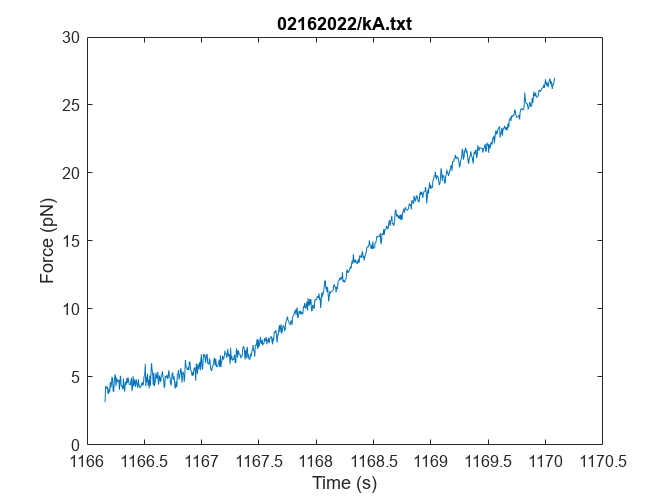

  load stretches.mat
  stretch_type = "Unfold";
  s_list = s_unfold;
  if strcmp(stretch_type,'Refold')
    s_list = s_refold;
  end
  pp = [];
  for i = 1:numel(s_list)
    pp = [pp;string(s_list(i).text)];
  end
  
  selection = pp(3);
  s = s_list(selection == pp);
end
figure;
plot(s.t,s.f)
xlabel('Time (s)')
ylabel('Force (pN)')
title(s.file)

## Tuning parameters

  % Transitions are unlikely near the start of a stretch, so we exclude
  % potential transitions if abs(f-fstart) < dfstart
  dfstart = 4;  
  % At the end of a REFOLD stretch noise makes detections difficult:
  dfend = 1;  % Make sure that abs(f-fend) > dfend at transition.
  % No end restrictions for unfold stretches

  % Low slope parts at start or end of a stretch may confuse the detection 
  % algorithm, so eliminate start and end parts where the slope
  % is less that slopefrac*median(slope):
  slopefrac = 0.7;

  % Parameters for moving slope calculation and slope change detection
  % Again, these are not set in stone and may need adjusting
  nf = numel(s.f);
  if nf > 1000
    slopelength = 30;
    minpeak = 0.03;
  elseif nf > 300
    slopelength = 10;
    minpeak = 0.05;
  else
    slopelength = 5;
    minpeak = 0.1;
  end

## Pre-processing

### Make sure all output variables are set:

  force = NaN;
  dx = NaN;
  Fdot = NaN;
  xpos = NaN;
  shift = NaN;

  % Make sure s.x>0 and the s.x and s.f both increase or decrease together
  s.x = s.x - min(s.x);

### Change sign of x and f for refolding stretches

This lets us use the same algorithm for bot unfolding and refolding

  sgn = sign(s.f(end) - s.f(1));
  f = sgn*s.f;
  x = sgn*s.x;
  t = s.t;

### Do not accept very short stretches

  df = f(end)-f(1);  % range of forces
  if(df<10)  % Skip if force amplitude is small (probably noise only)
    k = -1;
    return
  end

### Eliminate bad parts at start and end

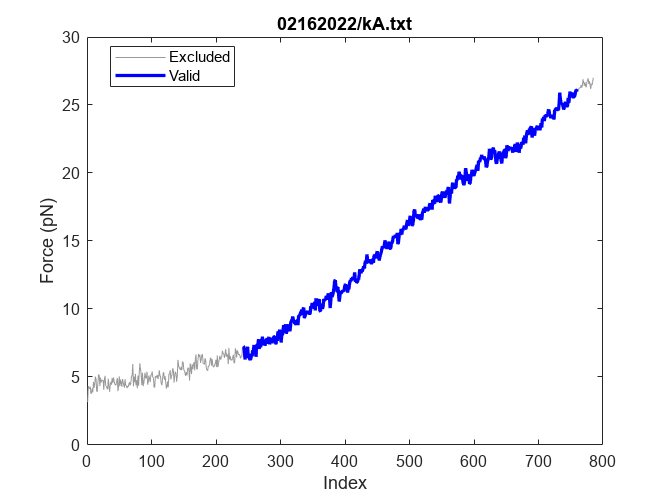

  slope = movingslope(f,slopelength);
  medslope = median(slope);
  startslope = find(slope>slopefrac*medslope,1);  % End of inital flat part 
  startmin = find(abs(f(1)-f)>dfstart,1);
  start = max([1,startslope,startmin]);
  stopslope = find(slope>slopefrac*median(slope),1,'last'); 
  stopmin = find(f(nf) - f > dfend,1,'last');
  stop = min([stopmin,stopslope,nf]);
  validrange = start:stop;

  figure;
  plot(s.f,'Color',0.6*[1 1 1])
  xlabel('Index')
  ylabel('Force (pN)')
  hold on;
  plot(start:stop,sgn*f(validrange),'b','LineWidth',2)
  title(s.file)
  legend('Excluded','Valid','location','best')
  hold off

## Find transitions (unfolding or refolding events)

### Find slope changes

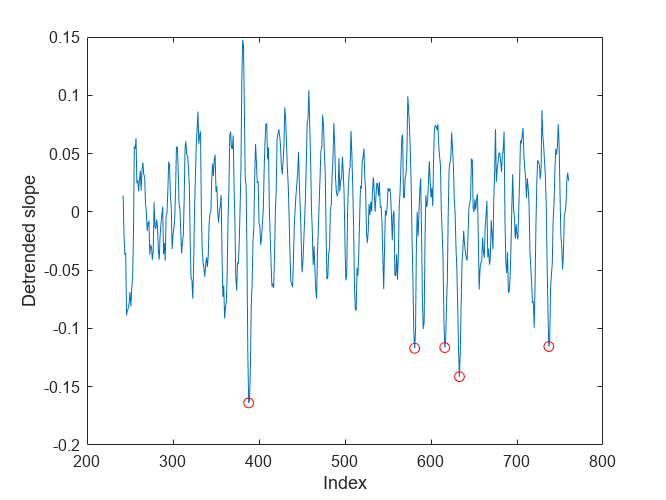

  slope = slope(validrange);
  dslope = detrend(slope);
  warning('off','signal:findpeaks:largeMinPeakHeight')
  [valleys,valley_ix] = findpeaks(-dslope,'MinPeakHeight',minpeak,...
    'MinPeakDistance',10,'SortStr','descend');
  warning('on','signal:findpeaks:largeMinPeakHeight')  

  if isempty(valley_ix)
    fprintf('No significant slope changes\n')
    k = -2; % No transition found
    return
  end 

  ixvalleys = valley_ix + start - 1;  % Index relative to start of stretch
  validvalleys = valleys>valleys(1)*0.7;
  valleys = valleys(validvalleys);
  ixvalleys = ixvalleys(validvalleys);
  if sgn == -1
    too_soon = f(ixvalleys) <= -20;  % Do not accept refolding at high force
    ixvalleys(too_soon) = [];
    valleys(too_soon) = [];
  end

  figure;
  plot(validrange,dslope,ixvalleys,dslope(ixvalleys-start+1),'or')
  xlabel Index
  ylabel('Detrended slope')

Note that we change the sign of the slope for refolding stretches, so that both unfolding and refolding events show up as drops (i.e., valleys) in slope.

## Examine up to ten of the deepest valleys

The valleys are ordered from the deepest to shallower.  We accept the deepest that seems OK.

  px = polyfit(validrange,x(validrange),1);  % Fit straight line to x to combat noise
  dt = (t(end)-t(1))/(nf-1);  % Time step
  k = 0;
  ii = 1;

  %  *** Search among valleys to find the first valid event ****
  while k<1 && ii <= min(numel(valleys),10)
    [k,force,dx,Fdot,ixfitb,pb,ixfita,pa,shift] = check_event(ixvalleys(ii),f,start,stop,px,dt,sgn);
    ii = ii + 1;
  end

index 385: Good transition


  if k<1
    disp('No valid transition found')
    return   % No valid event found
  end

## Plot result

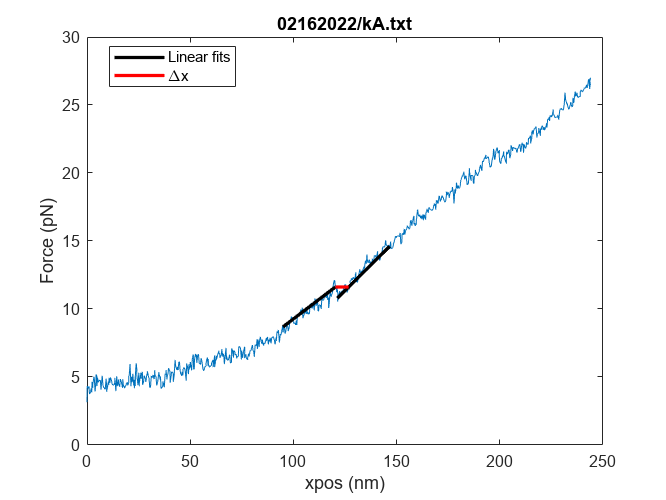

  xfit = sgn*polyval(px,ixfitb(1):ixfita(end));
  xpos = sgn*polyval(px,k);        % x at transition
  h = plot(sgn*x,sgn*f,xfit(1:numel(ixfitb)),sgn*polyval(pb,ixfitb),'k',...
    xfit(end-numel(ixfita)+1:end),sgn*polyval(pa,ixfita),'k');
  hold on;
  h(4) = plot([xpos,xpos+sgn*dx],force*[1,1],'r');
  hold off
  set(h(2:4),'linewidth',2)
  xlabel('xpos (nm)');
  ylabel('Force (pN)')
  title(s.file);
  legend(h([2,4]),'Linear fits','\Deltax','location','best')

## Output

fprintf('Transition index: %d\n',k); fprintf('Transition force: %5.2fpN\n',force);fprintf('Delta x         : %5.2fnm\n',dx);fprintf('Fdot            : %5.2fpN/s\n',Fdot);fprintf('Force shift     : %5.2fpN\n',shift)

Transition index: 385
Transition force: 11.62pN
Delta x         :  6.44nm
Fdot            :  7.41pN/s
Force shift     :  0.97pN


## Function check_event

function [k,force,dx,Fdot,ixfitb,pb,ixfita,pa,shift] = check_event(ixvalley,f,start,stop,px,dt,sgn)
  % Check if the event at ixvalley is a valid transition
  % Returns k = NaN if not valid
  force = NaN;
  dx = NaN;
  Fdot = NaN;
  pa = 0;
  pb = 0; 
  ixfita = [];
  ixfitb = [];
  shift = NaN;

  nf = numel(f);
  % Find highest f value before ixvalley
  peakrange = max(ixvalley-10,1):ixvalley;
  [~,m] = max(f(peakrange));
  k = peakrange(1) - 1 + m;
  [~,m] = min(f( k+1:min(nf,k+12)));
  i2 = k+m;   % Lowest value after transition


  if k-start < 3 || stop-i2 < 3 % not enough points for fitting pa0 or pb0
    fprintf('index %d: Not enough good point to fit straght line\n',k)
    k = -3;
    return
  end      

  % Fit lines before and after (potential) transition
  fitL = round(nf/10);  % Fit length
  ixfitb = max(start,k-fitL):k;
  ixfita = k+3:min(k+fitL+3,stop);
  fb = f(ixfitb);
  fa = f(ixfita);
  pb1 = polyfit(ixfitb,fb,1);
  pa1 = polyfit(ixfita,fa,1);
  dfb = fb-polyval(pb1,ixfitb)';  
  dfa = fa-polyval(pa1,ixfita)';

  %E.g.: For unfolding, fit to only unfolded points before the potential
  % transition and only folded points after
  shift1 = polyval(pb1,k)-polyval(pa1,k);
  ok_b = dfb > -shift1*0.08;   % Points near the lines
  ok_a = dfa < shift1*0.08;
  if sum(ok_a) < 3 || sum(ok_b) <3
    fprintf('index %d: Not enough good point to fit straght line\n',k)
    k = -4;  % To few relevant points for meaningful fit
    return
  end
  pb = polyfit(ixfitb(ok_b),fb(ok_b),1);
  pa = polyfit(ixfita(ok_a),fa(ok_a),1);
  if max(abs(pa(1)/pb(1)-1),abs(pb(1)/pa(1)-1)) > 0.5
    fprintf('index %d: Slope before and after differ too much\n',k);
    k = -5;  % Slope before and after differ too much
    return
  end
  
  force = sgn*polyval(pb,k);   % Force at transition
  shift = polyval(pb,k)-polyval(pa,k);
  noise = 4*std(f(ixfitb(ok_b))-polyval(pb,ixfitb(ok_b))');
  if sgn == 1
    noiselimit = max(noise,0.6+0.4*noise);  % higher limit if noise is low
  else
    noiselimit = max(noise,0.35+0.65*noise);  % shift is lower for refoling
  end
 
  if shift < noiselimit || force >50
    fprintf('index %d: Force shift too small compared to noise\n',k)
    k = -6;  % Too small shift
    return
  end

  % Rounding gives unnecessary discretization of dx
  recovery_ix = (sgn*force-pa(2))/pa(1);  
  dx = px(1)*(recovery_ix-k);
  Fdot = pb(1)/dt;
  if abs(dx) > 30
    fprintf('index %d: Delta x too small\n',k)
    k = -7;   % Too small dx
  end
  fprintf('index %d: Good transition\n',k)
end
